**1**

plNum = 4;
A1 = 2 * (mod(plNum, 2) + 1)

A1 = 2

A2 = 6 * (mod(plNum, 3) + 1)

A2 = 12

wA = mod(plNum, 5) + 2

wA = 6

wB = mod(plNum, 7) + 7

wB = 11

wC = mod(plNum, 9) + 1

wC = 5

syms t
x = A1 * sin(wA * t) * cos(wB * t) + A2 * cos(wC * t) ^ 2;

**1.1**

syms n Ts
xn = subs(x, t, n*Ts);

**1.2**

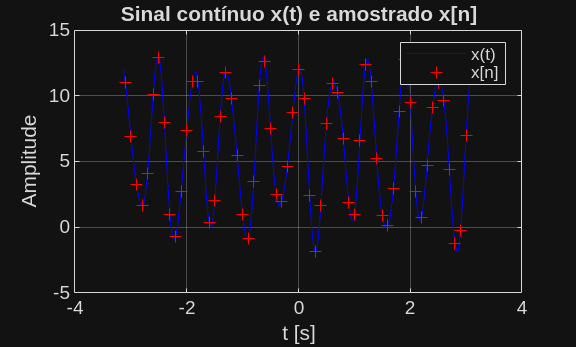

tDis = linspace(-pi, pi, 1000);
TsVal = 0.1;
nDis = fix(tDis / TsVal);
xSub = subs(x, t, tDis);
xnSub = subs(xn, {n Ts}, {nDis TsVal});
figure;
plot(tDis, xSub, '-b');
hold on;
plot(nDis*TsVal, xnSub, '+r');
xlabel('t [s]');
ylabel('Amplitude');
title('Sinal contínuo x(t) e amostrado x[n]');
legend('x(t)', 'x[n]');
grid on;

**2.1**

function result = energiaTrapezios(func, ti, tf, N)
arguments (Input)
	func
	ti
	tf
	N
end

arguments (Output)
	result
end

syms t
h = (tf - ti) / N;
tVec = ti:h:tf;
fVals = double(subs(func, t, tVec));
result = ((fVals(1) + fVals(end)) / 2 + sum(fVals(1:end-1))) * h;

end

function result = energiaSimpson(func, ti, tf, N)
arguments (Input)
	func
	ti
	tf
	N
end

arguments (Output)
	result
end

if mod(N, 2) ~= 0
	N = N + 1;
end

syms t
h = (tf - ti) / N;
tVec = ti:h:tf;
fVals = double(subs(func, t, tVec));
iEven = 2:2:N;
iOdd = 3:2:N - 1;
result = h / 3 * (fVals(1) + fVals(end) + 4 * sum(fVals(iEven)) + 2 * sum(fVals(iOdd)));

end

**2.2**

exp = abs(x) .^ 2;
ti = -pi

ti = -3.1416

tf = pi

tf = 3.1416

N = 1000 

N = 1000

Et = energiaTrapezios(exp, ti, tf, 1000)

Et = 346.4800

Es = energiaSimpson(exp, ti, tf, 1000)

Es = 345.5752

**2.2.1**

Ee = double(int(exp, t, ti, tf))

Ee = 345.5752

**2.2.2**

ErroT = Ee - Et

ErroT = -0.9048

ErroS = Ee - Es

ErroS = 0

**2.3**

TsVal = 0.1

TsVal = 0.1000

expDis = abs(xn) .^ 2;
nDis = fix(ti:TsVal:tf / TsVal);
expDisSubs = double(subs(xn, {n Ts}, {nDis TsVal}));
Ee = sum(expDisSubs) * TsVal

Ee = 211.2135